# Noise Variances

% Run script
run('Noise_estimation.m');

Launching ROS Core...
.Done in 1.8029 seconds.
Initializing ROS master on http://12.0.10.178:11311.
Initializing global node /matlab_global_node_77981 with NodeURI http://Gioels-MBP:49920/ and MasterURI http://localhost:11311.


Error using Noise_estimation
Cannot determine the message type of the /qualisys/Super_marker_1/odom topic. Either the topic is not registered with the ROS master, or the ROS master is not reachable.

Error in run (line 91)
evalin('caller', strcat(script, ';'));

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% Marker is placed in the : shoulder --> 1
%                           forearm  --> 2
%                           hand     --> 3
% Human arm parameters
% run('human_arm_param.m');
% marker.links = [1;
%                 1;
%                 1;
%                 1;
%                 2;
%                 2;
%                 2;
%                 3;
%                 3];
% 
% sample_Time = 0.01;
% % Change directory
% cd 'C code/S4_F3_H2/';
% 
% % Run script
% mex_generation(marker.links, sample_Time);
% cd ../..;

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

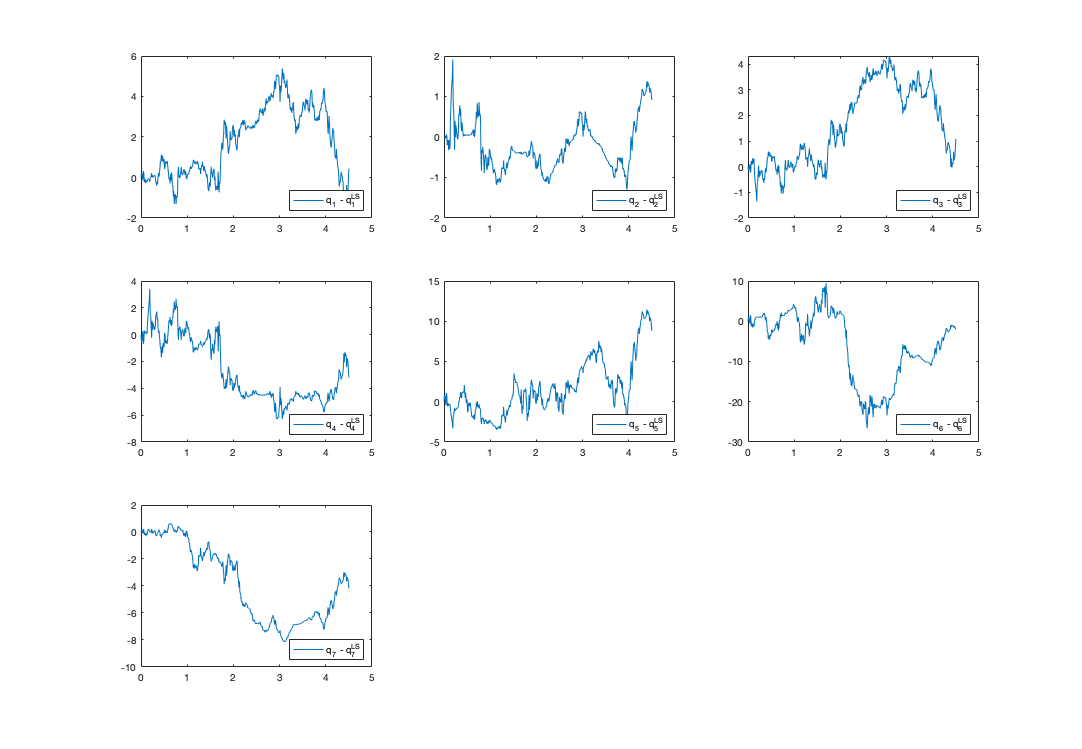

% Model IC 
q0_model = zeros(n, 1);
% LS IC
q0_LS = zeros(n, 1);

% Results
LS_KF_EKF_NLDM('LS', 'free', [], [], [], 'S4_F3_H2');

## 2.  WRONG GUESS OF INITIAL CONDITION q0 

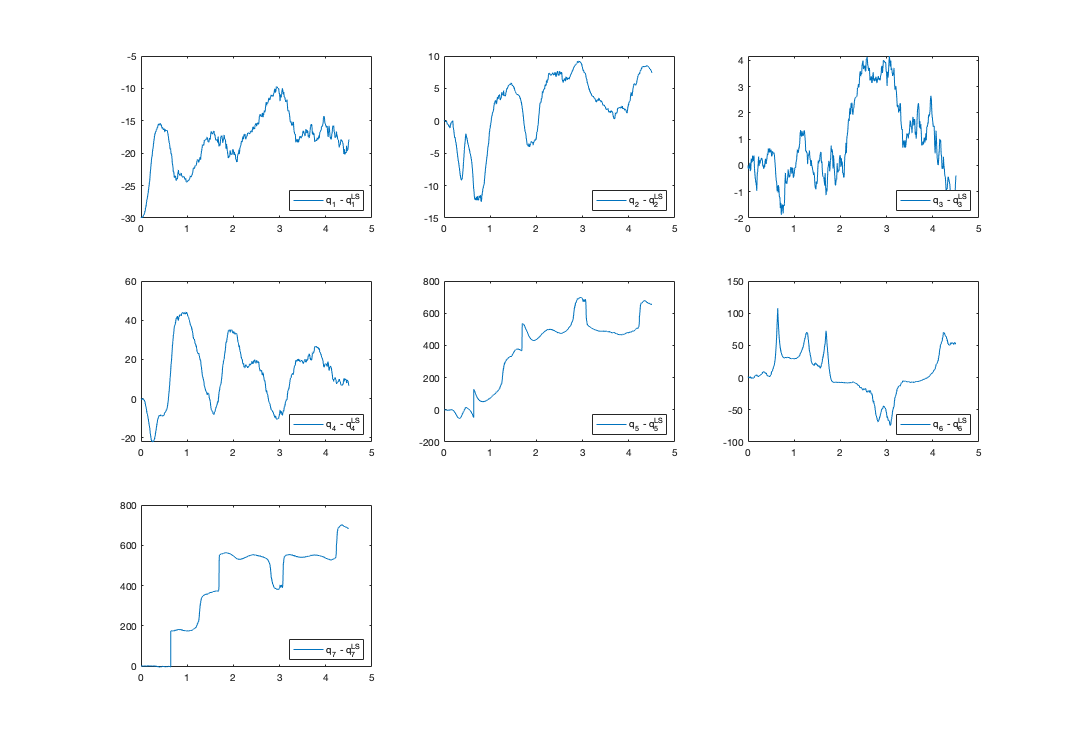

% Model IC 
q0_model = zeros(n, 1);
% LS IC
q0_LS = [deg2rad(30);
         zeros(n-1, 1)];

% Results
LS_KF_EKF_NLDM('LS', 'free', [], [], [], 'S4_F3_H2');

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{\tilde{u}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{\tilde{u}}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{\tilde{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{\tilde{u}}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

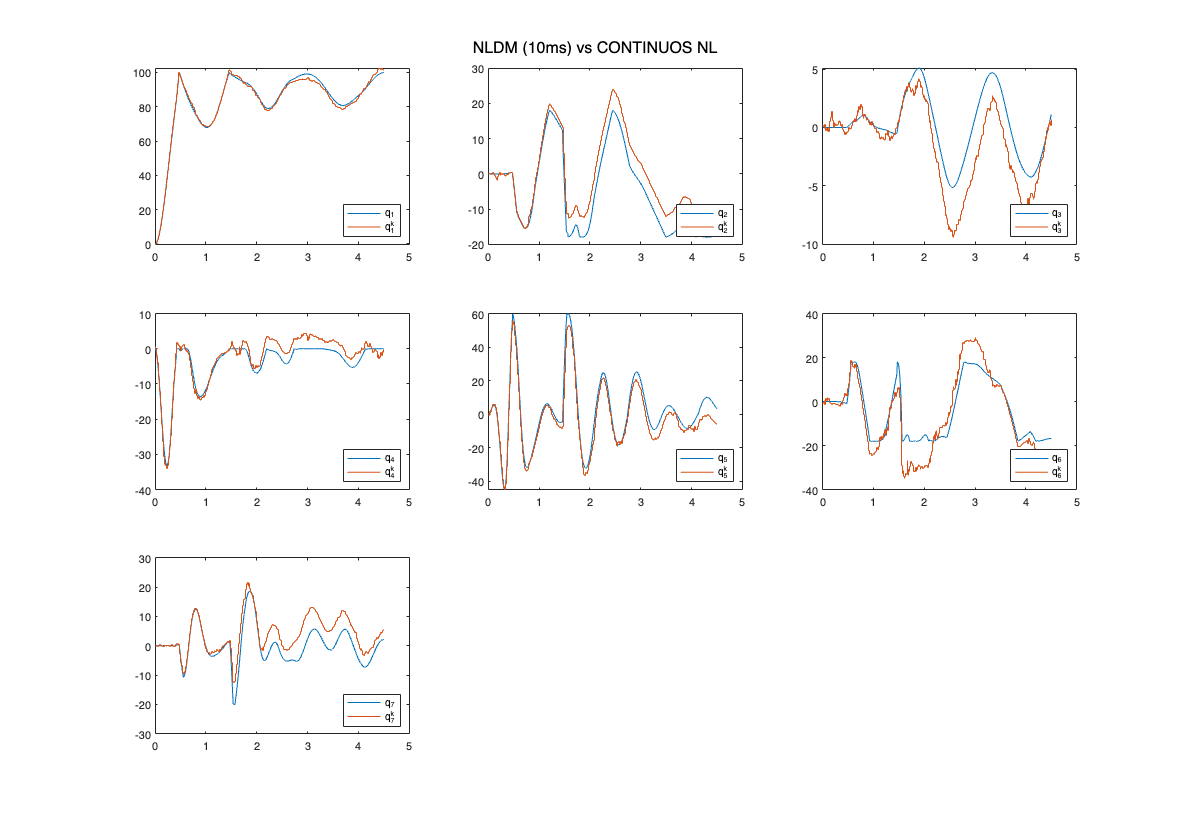

ans = 1.0e-04 *

    0.1196
    0.1801
    0.0058
    0.2239
   -0.0226
    0.0470
   -0.1162


ans = 1.0e-04 *

    0.0256   -0.0923   -0.0296   -0.1880   -0.2209   -0.1696   -0.1158   -0.1165   -0.1893    0.0153
    0.1189   -0.1011    0.0018    0.0538   -0.0477    0.0515    0.0460   -0.0541   -0.0534    0.0530
   -0.1364   -0.0421    0.1225   -0.0075    0.0563   -0.1062    0.0030    0.0564   -0.1342    0.0339
   -0.1534   -0.0310    0.0911   -0.0321   -0.0214    0.1524    0.0311   -0.0278    0.0399    0.0505
    0.0365    0.0547   -0.0219    0.0061    0.1187    0.0722    0.0999    0.0445   -0.0733    0.0151
    0.0462   -0.1077   -0.2082   -0.0084    0.0872    0.0730    0.0647   -0.0211    0.0015   -0.1519
    0.1135    0.0866    0.0683    0.0981    0.0580    0.1534    0.0845    0.1542   -0.0502    0.0635


ans = 1.0e-04 *

   -0.1594    0.0110    0.0787   -0.0002    0.0093   -0.0378   -0.1483   -0.0044    0.0961    0.1738
   -0.0430   -0.1627    0.0166    0.0376   -0.0227   -0.1149    0.2024   -0.2360   -0.0510   -0.1322
   -0.0636    0.0318    0.0138   -0.0711    0.0777    0.0622    0.0647   -0.0426    0.1049    0.0661
    0.2509    0.1063    0.1157    0.0053   -0.1288   -0.0371   -0.0758   -0.0564    0.0555   -0.0557
   -0.0895   -0.0409   -0.0161    0.0409   -0.0953    0.0317    0.0078    0.1324   -0.0213   -0.0134
   -0.1171   -0.1385    0.0311   -0.0249    0.0504   -0.0893    0.1909    0.0122    0.1047   -0.0227
   -0.0163    0.0690    0.0556   -0.1120   -0.1533   -0.1098   -0.1416    0.0060   -0.0411   -0.0368


% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC 
q0_model = zeros(n, 1);

% Sample time is fixed at 0.01
LS_KF_EKF_NLDM('NLDM', 'free', [], [], [], 'S4_F3_H2');

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta \tilde{u}}_{k} = \mathbf{\tilde{u}}_k - \mathbf{u}_{eq} \\
\mathbf{\tilde{u}}_k = \mathbf{\bar{u}}_k + \mathbf{n}_k
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


In simulink, the above state space representaion was implemented. Th considered input was  $\mathbf{\Delta \tilde{u}}_k + \mathbf{n}_k$, so that $\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot (\mathbf{\Delta \tilde{u}}_k  + \mathbf{n}_k)$,            $\mathbf{n}_k \sim \mathcal{N}(0, \mathbf{N})$

The matrix $\mathbf{N}$ was computed such that $\mathbf{GNG^T} = \mathbf{Q}$

### 3.1 Free fall motion, eq. point (q_eq = 0, u_eq = 0)

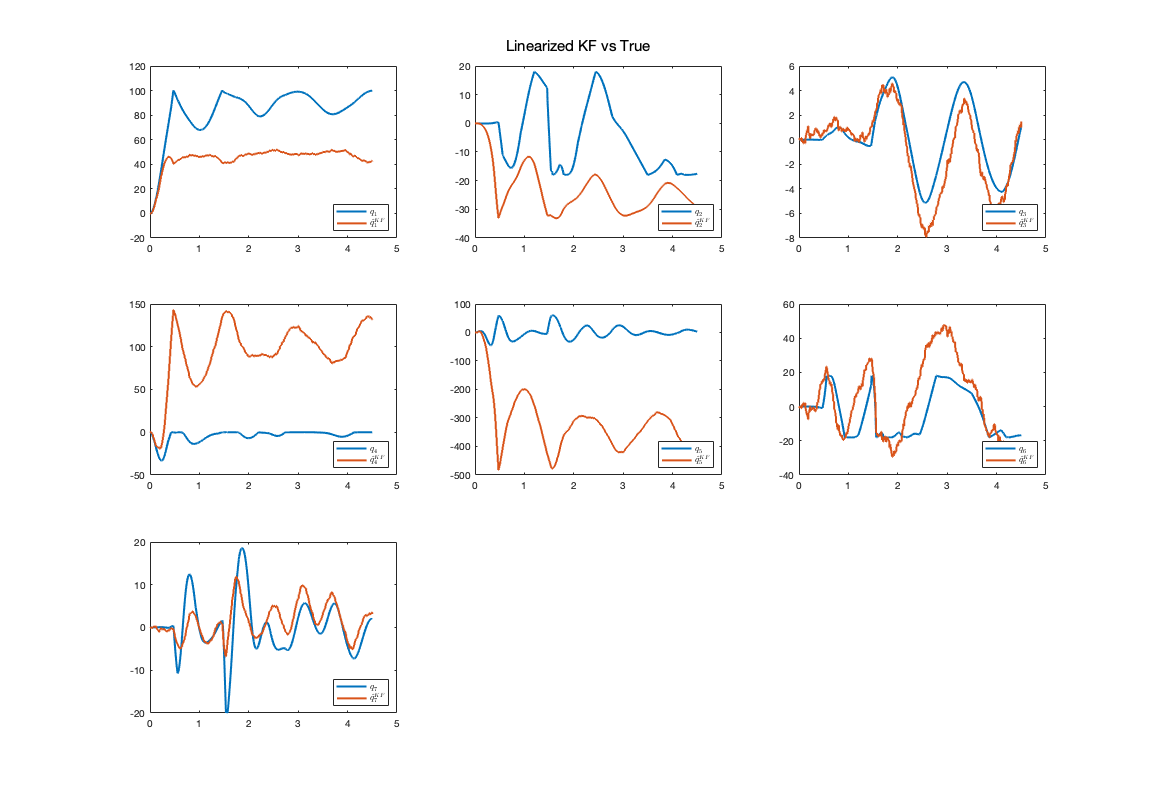

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = zeros(n, 1);

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Number of samples
number_samples = simulink.time/sample_Time;

% Results
LS_KF_EKF_NLDM('KF', 'free', marker, number_samples, 'S4_F3_H2');

### 3.2 Human arm motion close to the rest position

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°, except for $q_1$ which is set to 87°.


$$q_0 = \pmatrix{87\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{90 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The model is now expected to simulate better the human arm motion.

The comparison between simulation and linearized discrete state-space is reported below.

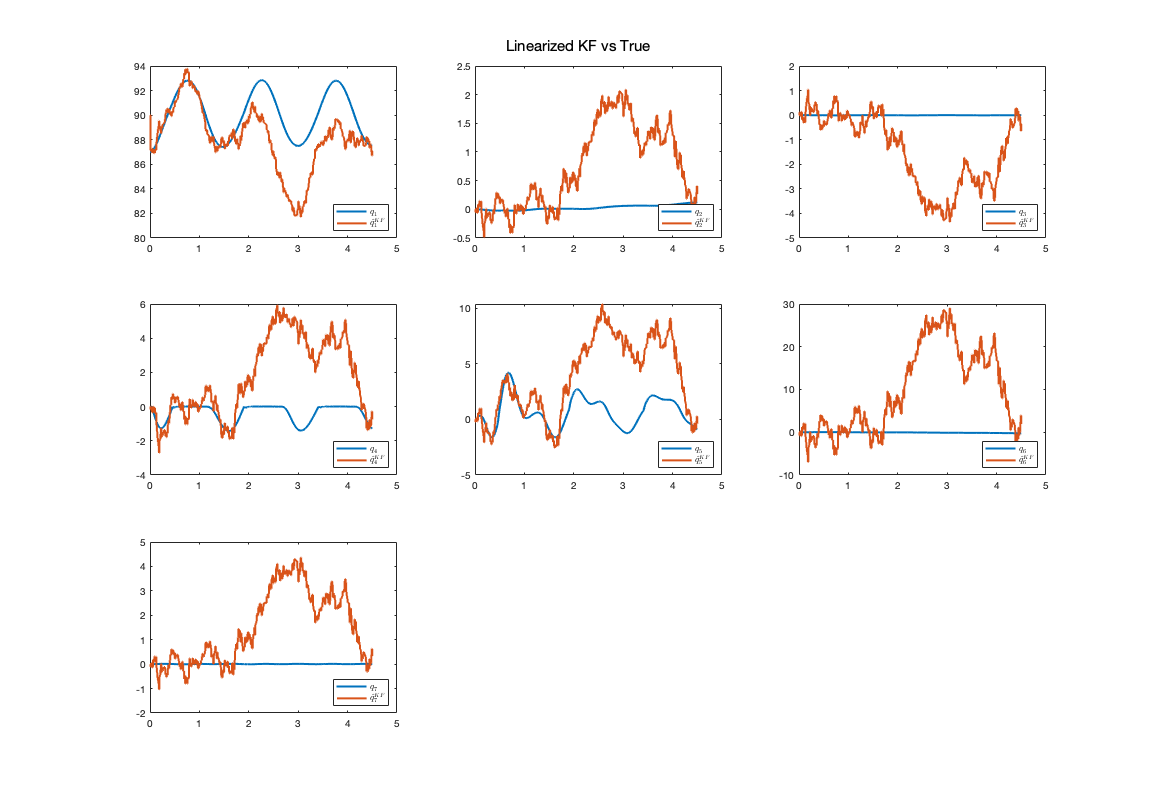

% Model IC
q0_model = [deg2rad(87); zeros(n-1, 1)];

% Equilibrium point
kf.q_eq = [pi/2; zeros(n-1, 1)];
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM('KF', 'free', marker, number_samples, 'S4_F3_H2');

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
\\
\mathbf{G}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{u}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

clf;
% Human Arm IC SIMULATION [rad]
simulink.q0 = zeros(n, 1);

% Joints' trajectory
% q1
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));

% q2
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_roty', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));

% q3
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));

% q4
set_param('master_thesis_simulink/System/Human arm/Elbow_joint/jRightElbow_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/Elbow_joint', get_param('master_thesis_simulink/System/Human arm/Elbow_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/Elbow_joint/jRightElbow_rotx', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/Elbow_joint', get_param('master_thesis_simulink/Human arm/Elbow_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/Elbow_joint/jRightElbow_rotx', 'PortHandles').LConn(2));

%
%% LINEARIZED KALMAN FILTER
%

% Equilibrium point
kf.equilibrium_q = [0; pi/4; pi/4; pi/4; zeros(n-4, 1)];
kf.equilibrium_u = zeros(3*m, 1);

% F matrix --> df/dq evaluated at the equilibrium point q_eq, u_eq = 0
kf.F = full(functions.f_Fekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));
% G matrix --> df/du evaluated at the equilibrium point q_eq, u_eq = 0
kf.G = full(functions.f_Gekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));

% H matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
kf.H = full(functions.f_J(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% J matrix --> dPhi/du = 0 
kf.J = zeros(3*m, 3*m);

% Set initial condition
kf.q0 = simulink.q0;

%kf.Nu = diag(noise.input_var);

% Process covariance matrix
%kf.Q = kf.G * kf.Nu * kf.G';
kf.Q = diag(noise.process_var);

% Measurement covariance matrix
kf.R = 10e-5 * diag(noise.measurement_var);

% Initial state estimate Delta_q0
kf.x0est = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 1 * eye(n);

% List of Pk for k = 1, .., N
kf.Pk = [kf.P0];
% List of Pk_ for k = 1, .., N
kf.Pk_ = [];
% List of Kk for k = 1, .., N
kf.Kk = [];

% Compute Pk, Pk_, Kk offline
for k = 1 : simulink.time/sample_Time

    Pk_ = kf.F * kf.Pk(1:n, n*(k-1)+1:n*(k-1)+n) * kf.F' + kf.Q;
    Kk = Pk_ * kf.H' / (kf.H * Pk_ * kf.H' + kf.R);
    Pk = (eye(n) - Kk * kf.H) * Pk_ * (eye(size(kf.F, 1)) - Kk * kf.H)' + Kk * kf.R * Kk';
    kf.Pk_ = [kf.Pk_, Pk_];
    kf.Kk = [kf.Kk, Kk];
    kf.Pk = [kf.Pk, Pk];

end

%
%% EXTENDED KALMAN FILTER
%

% Extended Kalman Filter 'on'
set_param('master_thesis_simulink/System/Extended Kalman Filter','commented','off');

% Set initial condition
ekf.q0 = simulink.q0;

% NLDM IC
set_param('master_thesis_simulink/System/NLDM delay', 'InitialCondition', 'ekf.q0');

% Process covariance matrix
% ekf.Nu = diag(noise.input_var);
ekf.Q = diag(noise.process_var);

% Measurement covariance matrix
ekf.R = 10e-2 * diag(noise.measurement_var);

% Initial state estimate Delta_q0
ekf.q0est = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = 1 * eye(n);

% Simulation
output_8 = sim("master_thesis_simulink.slx");

% Plot KF estimate vs EKF estimate
fig_8 = figure(8);
sgtitle("LKF vs EKF vs True");

for i = 1 : n

    q = strcat('$q_', num2str(i), '$');
    qkf = strcat('$\hat{q}^{KF}_', num2str(i), '$');
    qekf = strcat('$\hat{q}^{EKF}_', num2str(i), '$');
    set(fig_8, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_8.q.time, rad2deg(output_8.q.signals.values(:, i)), 'LineWidth', 2);
    hold on;
    stairs(output_8.qk_kf.time, rad2deg(squeeze(output_8.qk_kf.signals.values(i, :))'), 'LineWidth', 2);
    hold on;
    stairs(output_8.qk_ekf.time, rad2deg(squeeze(output_8.qk_ekf.signals.values(i, :))'), 'LineWidth', 2);
    legend(q, qkf, qekf, 'Location', 'southeast', 'Interpreter', 'latex');
end

% Uncomment joints' trajectory
% q1
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));

% q2
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));

% q3
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));